# Remove independent noise from functional brain microscopy data with a Deep Interpolation AI model

This example imports and applies a pretrained AI model using the DeepInterpolation concept[1] into MATLAB to denoise a small snippet of time-series microscopy image data representing live neural function.

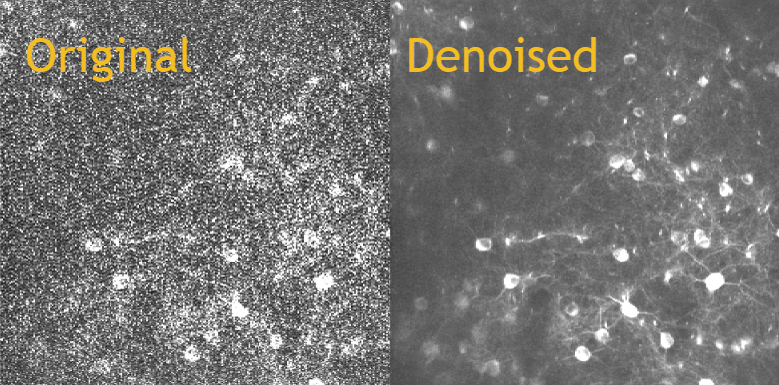

## About the AI Model & Sample Data

The DeepInterpolation originators' reference code implementation in Python[2] provides links to a set of cloud-hosted pretrained AI models, each trained on a specific experimental modality and configuration. This example uses the *Two-photon Ai93 excitatory line *pretrained model (120MB) trained on calcium imaging data of live excitatory neurons expressing a calcium indicator and collected with a two-photon microscope. It denoises the *tiny_ophys* sample data (included directly with [2]) which contains substantially similar data. 

## Pipeline Preview

This example will step through the following top-level pipeline steps:

- Import the image time-series sample data (TIFF volume)

- Import the pretrained model (DeepInterpolation concept)

- Configure data to model streaming

- Preprocess image time-series data

- Denoise data with DeepInterpolation concept

- Postprocess and visualize denoising results

See the [Outline panel](https://www.mathworks.com/help/matlab/matlab_prog/edit-and-format-code.html#mw_e5629e25-311d-433f-a064-8b11516d5a1e) for more granular section-by-section components. 

exampleInfo = setupExample(); % Download model & sample data & setup environment, and return example metadata

## Import the image time-series sample data (TIFF volume)

ophys = single(tiffreadVolume('ophys_tiny_761605196.tif'));
size(ophys)

ans =    512   512   100


sampleDataNumFrames = size(ophys,3); 

The TIFF volume sample data is a time-series image stack with 100 frames (timesteps) each covering an area spanned by 512 by 512 pixels. 

### Inspect noise level of raw data

By viewing a few frames we can get a sense of the noise level of the input data: 

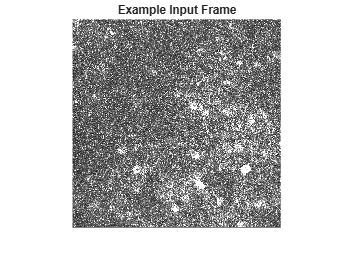

frameIndex = 50;
imshow(ophys(:,:,frameIndex), [0 prctile(ophys(:),95)])
title("Example Input Frame")

Whichever frame is inspected, the high level of independent noise significantly obscures the details near the neurons, whose cell bodies (somata) are visible as bright spots of approximately 100 square pixels. 

## Import the pretrained model (DeepInterpolation concept)

The original pretrained model is in a TensorFlow-Keras network format, which can be [imported into MATLAB](https://www.mathworks.com/help/deeplearning/ref/importkerasnetwork.html) but is no longer recommended. Therefore the model was converted to a TensorFlow file folder format using a Python script, and compressed into a ZIP file and stored in the cloud. This ZIP file was downloaded during example setup:

exampleInfo.modelZipFile

ans = '/MATLAB Add-Ons/Collections/DeepInterpolation-MATLAB/pretrainedModels/TensorFlowNetworks/TF_2019_09_11_23_32_unet_single_1024_mean_absolute_error_Ai93-0450.zip'

This ZIP file was also automatically unzipped during example setup, showing the Tensorflow folder structure of a model, including metadata from the original Tensorflow-Keras network:

dir(exampleInfo.modelFolder)


.                  ..                 assets             keras_metadata.pb  saved_model.pb     variables          



The function [`importNetworkFromTensorFlow`](https://www.mathworks.com/help/deeplearning/ref/importnetworkfromtensorflow.html?websocket=on)  imports the contents from the TensorFlow folder contents into the [`dlnetwork`](https://www.mathworks.com/help/deeplearning/ref/dlnetwork.html) format used by Deep Learning Toolbox:

importednet = importNetworkFromTensorFlow(exampleInfo.modelFolder, Namespace='trainedModel');

Importing the saved model...
Translating the model, this may take a few minutes...
Finished translation. Assembling network...
Import finished.


### Inspect the Network

The function [`analyzeNetwork`](https://www.mathworks.com/help/deeplearning/ref/analyzenetwork.html) can be used to visualize and understand the architecture of this pretrained network built on the DeepInterpolation concept: 

%netInfo = analyzeNetwork(importednet);

The imported network shows layers of downsampling followed by upsampling as described in the originators' publication[1]. 

The first layer of the network indicates the input size of data the pretrained model expects, which is saved here for later use: 

modelInputSize = importednet.Layers(1).InputSize

modelInputSize =    512   512    60


modelWindowNumFrames = modelInputSize(3);

The model expects input frames of 512 by 512 pixels, matched to the sample data frame size found above. It also has a "window size" of 60 frames, which is a bit shorter than the sample data length of 100 frames. 

## Preprocess data 

### Normalization of image frames

Calcium imaging reports on neural activity through *relative *brightness changes over short timescales. DeepInterpolation models are thus trained on normalized image data of mean zero (0) and standard deviation (1). The convenience function [`normalize`](https://www.mathworks.com/help/matlab/ref/double.normalize.html?overload=normalize+false&websocket=on) can be used to used to shift and scale the sample data accordingly:  

[ophys, C, S] = normalize(ophys,3,"center","mean","scale","std"); %  Normalize along the time dimension (3) to mean of zero (0) and standard deviatoin of one (1)

For the default normalization used, the centering (`C`) and scaling (`S`) variables returned represent the mean and standard deviation per pixel, respectively, and can be used to renormalize after processing. 

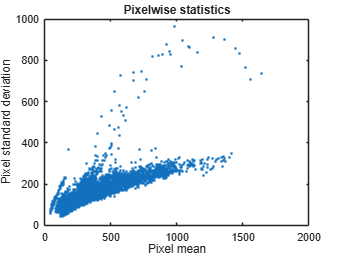

h = plot(C(:),S(:),".");
xlabel("Pixel mean"), ylabel("Pixel standard deviation")
title("Pixelwise statistics")

The sample data contains pixels with at least three clusters of image statistics. 

## **Configure data streaming pipeline**

Typical  data would be much longer than the short data sample (100 frames; 3.33 seconds) demonstrated here, and data would be streamed pixel-wise to the model for either *training *(learning to distinguish current-time signal from time-independent noise sources) or *inference* (applying denoising to data with similar noise characteristics). 

Since this example uses a short data sample of similar length to the model window size (60 frames; 2 seconds) observed above, inference (denoising), the streaming will be performed directly. The only configuration needed is to select the offset (if any) from the sample data center frame: 

streamingConfig = "direct"; %Options are "Direct" and "Datastore" [future]
maxSampleDataOffset = floor((sampleDataNumFrames - modelWindowNumFrames)/2);
minSampleDataOffset = -maxSampleDataOffset;
sampleDataOffset = 0;

The README of the reference code implementation[2] depicts how typical input data is streamed differently during model training and inference, notably omitting one or more central frames during training, enabling the model to learn to distinguish current-time and time-independent sources. 

For streaming with longer input data, this package includes a custom [datastore](https://www.mathworks.com/help/deeplearning/ug/datastores-for-deep-learning.html) configurable for either the training or inference processing use cases. Though unnecessary, it can also be applied here in the trivial non-streaming case for comparison purposes. To verify this yields the same results, update `streamingConfig` to "Datastore" above. 

if streamingConfig == "Datastore"
    numOmittedFrames = 0; % omitted frames are not needed (nor sensible) for inference
    %Future implementation
end

## **Denoise image time-series data using a DeepInterpolation model**

This example will use the [`predict`](https://www.mathworks.com/help/deeplearning/ref/dlnetwork.predict.html) function in Deep Learning Toolbox to perform inference, applying the DeepInterpolation pretrained model to the sample data input. Since the pretrained model learned to distinguish current-time from time-indenpendent sources and minimize the latter, this inference process will denoise the input data. 

% Create output array matched in size to the input sample data
ophysinterp = zeros(size(ophys)); 

% Create shiftable frame window to be input to the DeepInterpolation model
windowOffsets = -modelWindowNumFrames/2:((modelWindowNumFrames/2)-1);
maxStreamShift = sampleDataNumFrames - modelWindowNumFrames;

% Stream through sample data
startStreamIdx = (modelWindowNumFrames/2) + 1;
for streamIdx = startStreamIdx:(startStreamIdx+maxStreamShift)
    ophysinterp(:,:,streamIdx) = predict(importednet,ophys(:,:,streamIdx+windowOffsets));
end


## Postprocess and visualize denoising results

### Rescale normalized frames

The normalized sample data, and the denoised output computed from it, can now be shifted and scaled back to the original levels:image data levels: 

ophys  = (ophys .* S) + C;
ophysinterp = (ophysinterp .* S) + C;

### Show denoising results

The denoising results can be shown again using `imshow `comparing input (raw) and output (denoised) frames. A `for` loop is used to show a time-series of raw and denoised frames, to reveal any signs of live brain function: 

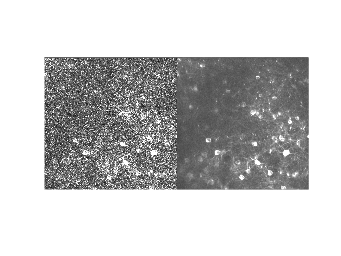

for idx = 31:size(ophys,3)-30
    imshow([ophys(:,:,idx) ophysinterp(:,:,idx)],...
        [0 prctile(ophys(:),95)]);  % scaling image to 0 .. 95 percentile to show range
    pause(0.1);
end

Near the bottom center, one neuron becomes brighter indicating the cell has "fired" an action potential, and the signal can be seen to propagate along a neurite (axon or dendrite) extending towards the right. This can be seen much more clearly in the denoised image frames. 

## References

- Lecoq, J., Oliver, M., Siegle, J.H. *et al.* Removing independent noise in systems neuroscience data using DeepInterpolation. *Nat Methods* **18**, 1401–1408 (2021). [https://doi.org/10.1038/s41592-021-01285-2](https://doi.org/10.1038/s41592-021-01285-2)

- https://github.com/AllenInstitute/deepinterpolation

## Helper Functions

function exampleInfo = setupExample()

exampleInfo.baseFolder = deepinterp.setup();
exampleInfo.modelZipFile = deepinterp.internal.getPretrainedModelFilename('TP-Ai93-450');

[p,f,~] = fileparts(exampleInfo.modelZipFile);
exampleInfo.modelRootFolder = p; % extract root folder of model ZIP file, to which its which its contents will be extracted 

unzip(exampleInfo.modelZipFile,exampleInfo.modelRootFolder); % unzip model contents into same root folder
exampleInfo.modelFolder = fullfile(p,f); % store path to folder containing extracted contents; this is the TensorFlow model

end
